clear; clc; close all;

% =========================================================================
% 1. CHARGEMENT DES DONNÉES
% =========================================================================
files_to_load = {
    "E:\Data\Aurelie\analysis\June2026\invivo_exvivo\119_220919plane0\alignment_analysis.mat";
    "E:\Data\Aurelie\analysis\June2026\invivo_exvivo\119_220923plane0\alignment_analysis.mat";
    "E:\Data\Aurelie\analysis\June2026\invivo_exvivo\582_230331plane0\alignment_analysis.mat";
    "E:\Data\Aurelie\analysis\June2026\invivo_exvivo\175_221125plane0\alignment_analysis.mat"
};
nb_files = length(files_to_load);

dataset_labels = cell(1, nb_files);

% Chargement dans un tableau de structures
for i = 1:nb_files
    % Création de labels propres pour l'affichage (ex: "119_220919")
    parts = strsplit(files_to_load{i}, '\');
    dataset_labels{i} = strrep(parts{end-1}, 'plane0', '');
    
    % On charge TOUS les modèles, ainsi que les données
    analysis_data(i) = load(files_to_load{i}, 'MdlLin', 'MdlSVM', 'MdlRF', 'cell_IDs', 'X_raw', 'Ycat_raw');
end

% =========================================================================
% 2. CROSS-TESTING (Double Boucle)
% =========================================================================
% Initialisation des 3 matrices d'accuracy
acc_matrix_lin = zeros(nb_files, nb_files);
acc_matrix_svm = zeros(nb_files, nb_files);
acc_matrix_rf  = zeros(nb_files, nb_files);

fprintf('Début du Cross-Testing pour LDA, SVM et RF...\n');

for m = 1:nb_files % Boucle sur les MODÈLES
    
    mod_lin = analysis_data(m).MdlLin;
    mod_svm = analysis_data(m).MdlSVM;
    mod_rf  = analysis_data(m).MdlRF;
    
    for d = 1:nb_files % Boucle sur les DATASETS (Données de test)
        
        c_IDs  = analysis_data(d).cell_IDs;
        X_test = analysis_data(d).X_raw(c_IDs, :);
        Y_test = analysis_data(d).Ycat_raw(c_IDs, :);
        
        % Extraction de l'accuracy pour chaque modèle
        acc_matrix_lin(m, d) = get_accuracy(mod_lin, X_test, Y_test);
        acc_matrix_svm(m, d) = get_accuracy(mod_svm, X_test, Y_test);
        acc_matrix_rf(m, d)  = get_accuracy(mod_rf, X_test, Y_test);
    end
end
fprintf('Cross-Testing terminé !\n');

% =========================================================================
% 3. AFFICHAGE DES GRAPHIQUES (3 HEATMAPS)
% =========================================================================

% --- Heatmap 1 : LDA ---
figure('Name', 'Cross-Testing Accuracy : LDA', 'Position', [100, 200, 500, 450]);
h1 = heatmap(dataset_labels, dataset_labels, acc_matrix_lin);
h1.Title = 'Modèle LDA (Accuracy Sans Noires)';
h1.XLabel = 'Dataset Testé';
h1.YLabel = 'Modèle Utilisé (Entraîné sur)';
h1.Colormap = parula; 
h1.CellLabelFormat = '%.1f%%'; 

% --- Heatmap 2 : SVM ---
figure('Name', 'Cross-Testing Accuracy : SVM', 'Position', [600, 200, 500, 450]);
h2 = heatmap(dataset_labels, dataset_labels, acc_matrix_svm);
h2.Title = 'Modèle SVM (Accuracy Sans Noires)';
h2.XLabel = 'Dataset Testé';
h2.YLabel = 'Modèle Utilisé (Entraîné sur)';
h2.Colormap = parula; 
h2.CellLabelFormat = '%.1f%%'; 

% --- Heatmap 3 : Random Forest ---
figure('Name', 'Cross-Testing Accuracy : Random Forest', 'Position', [1100, 200, 500, 450]);
h3 = heatmap(dataset_labels, dataset_labels, acc_matrix_rf);
h3.Title = 'Modèle Random Forest (Accuracy Sans Noires)';
h3.XLabel = 'Dataset Testé';
h3.YLabel = 'Modèle Utilisé (Entraîné sur)';
h3.Colormap = parula; 
h3.CellLabelFormat = '%.1f%%'; 




clear; clc; close all;

% =========================================================================
% 1. CHARGEMENT DES DONNÉES
% =========================================================================
files_to_load = {
    "E:\Data\Aurelie\analysis\June2026\invivo_exvivo\119_220919plane0\alignment_analysis.mat";
    "E:\Data\Aurelie\analysis\June2026\invivo_exvivo\119_220923plane0\alignment_analysis.mat";
    "E:\Data\Aurelie\analysis\June2026\invivo_exvivo\582_230331plane0\alignment_analysis.mat";
    "E:\Data\Aurelie\analysis\June2026\invivo_exvivo\175_221125plane0\alignment_analysis.mat"
};
nb_files = length(files_to_load);

dataset_labels = cell(1, nb_files);
for i = 1:nb_files
    parts = strsplit(files_to_load{i}, '\');
    dataset_labels{i} = strrep(parts{end-1}, 'plane0', '');
    % On charge juste ce dont on a besoin pour reconstruire et tester
    analysis_data(i) = load(files_to_load{i}, 'cell_IDs', 'X_raw', 'Ycat_raw', 'colorcell_exvivo');
end

% =========================================================================
% 2. DÉFINITION DES COMBINAISONS À ENTRAÎNER
% =========================================================================
% Vous pouvez définir manuellement quelles combinaisons vous voulez tester.
% Ici, on va tester : "1+2", "3+4", "1+2+3", et "Tous (1+2+3+4)"
combinations_to_train = {
    [1, 2],       '119_Both';
    [3, 4],       '582+175';
    [1, 4],     '119_1+175';
    [1,2, 4],     '119_both+175';
    [1, 2, 3],    '119+582';
    [1, 2, 3, 4], 'All_Animals'
};
nb_combos = size(combinations_to_train, 1);
combo_labels = combinations_to_train(:, 2)';

% =========================================================================
% 3. CRÉATION DES MODÈLES GROUPÉS ET TESTS
% =========================================================================
% Matrices pour stocker les résultats: Lignes = Combinaisons, Colonnes = Datasets testés
acc_matrix_lin = zeros(nb_combos, nb_files);
acc_matrix_svm = zeros(nb_combos, nb_files);
acc_matrix_rf  = zeros(nb_combos, nb_files);

fprintf('--- Création et Test des Modèles Groupés ---\n\n');

--- Création et Test des Modèles Groupés ---



Entraînement de la combinaison : 119_Both...



====== RÉSULTATS DE LA CROSS-VALIDATION ======
1. Linéaire (LDA)       : 80.90 %
3. SVM Multi-classes    : 80.56 %
4. Random Forest        : 80.23 %


Entraînement de la combinaison : 582+175...



====== RÉSULTATS DE LA CROSS-VALIDATION ======
1. Linéaire (LDA)       : 72.31 %
3. SVM Multi-classes    : 75.00 %
4. Random Forest        : 71.51 %


Entraînement de la combinaison : 119_1+175...



====== RÉSULTATS DE LA CROSS-VALIDATION ======
1. Linéaire (LDA)       : 83.45 %
3. SVM Multi-classes    : 85.74 %
4. Random Forest        : 84.86 %


Entraînement de la combinaison : 119_both+175...



====== RÉSULTATS DE LA CROSS-VALIDATION ======
1. Linéaire (LDA)       : 80.63 %
3. SVM Multi-classes    : 83.02 %
4. Random Forest        : 83.52 %


Entraînement de la combinaison : 119+582...



====== RÉSULTATS DE LA CROSS-VALIDATION ======
1. Linéaire (LDA)       : 74.65 %
3. SVM Multi-classes    : 76.70 %
4. Random Forest        : 75.80 %


Entraînement de la combinaison : All_Animals...


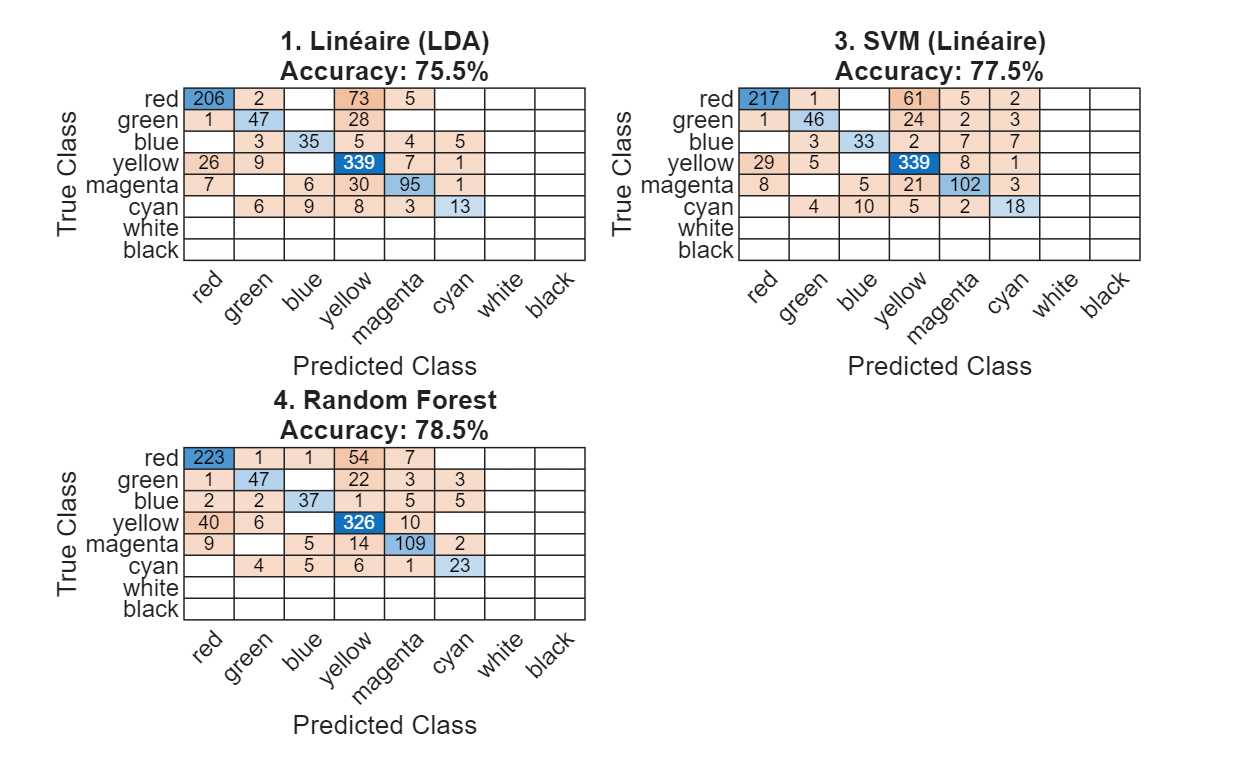


====== RÉSULTATS DE LA CROSS-VALIDATION ======
1. Linéaire (LDA)       : 75.46 %
3. SVM Multi-classes    : 77.52 %
4. Random Forest        : 78.54 %



for c = 1:nb_combos
    datasets_in_combo = combinations_to_train{c, 1};
    combo_name = combinations_to_train{c, 2};
    fprintf('Entraînement de la combinaison : %s...\n', combo_name);
    
    % a) Concaténation des données pour cette combinaison
    x_grouped = [];
    colorcell_grouped = [];
    
    for idx = datasets_in_combo
        c_IDs = analysis_data(idx).cell_IDs;
        x_grouped = [x_grouped ; analysis_data(idx).X_raw(c_IDs, :)];
        colorcell_grouped = [colorcell_grouped ; analysis_data(idx).colorcell_exvivo(c_IDs)];
    end
    
    % b) Entraînement des 3 modèles sur ce gros dataset
    [MdlLin_grp, MdlSVM_grp, MdlRF_grp, ~, ~, ~, ~, ~] = prediction_color(...
        colorcell_grouped, x_grouped(:,1), x_grouped(:,2), x_grouped(:,3), x_grouped(:,4));
    
    % c) Cross-Testing contre TOUS les datasets individuels (1 à 4)
    for d = 1:nb_files
        c_IDs_test = analysis_data(d).cell_IDs;
        X_test = analysis_data(d).X_raw(c_IDs_test, :);
        Y_test = analysis_data(d).Ycat_raw(c_IDs_test, :);
        
        acc_matrix_lin(c, d) = get_accuracy(MdlLin_grp, X_test, Y_test);
        acc_matrix_svm(c, d) = get_accuracy(MdlSVM_grp, X_test, Y_test);
        acc_matrix_rf(c, d)  = get_accuracy(MdlRF_grp,  X_test, Y_test);
    end
end

fprintf('\nTous les tests sont terminés !\n');


Tous les tests sont terminés !


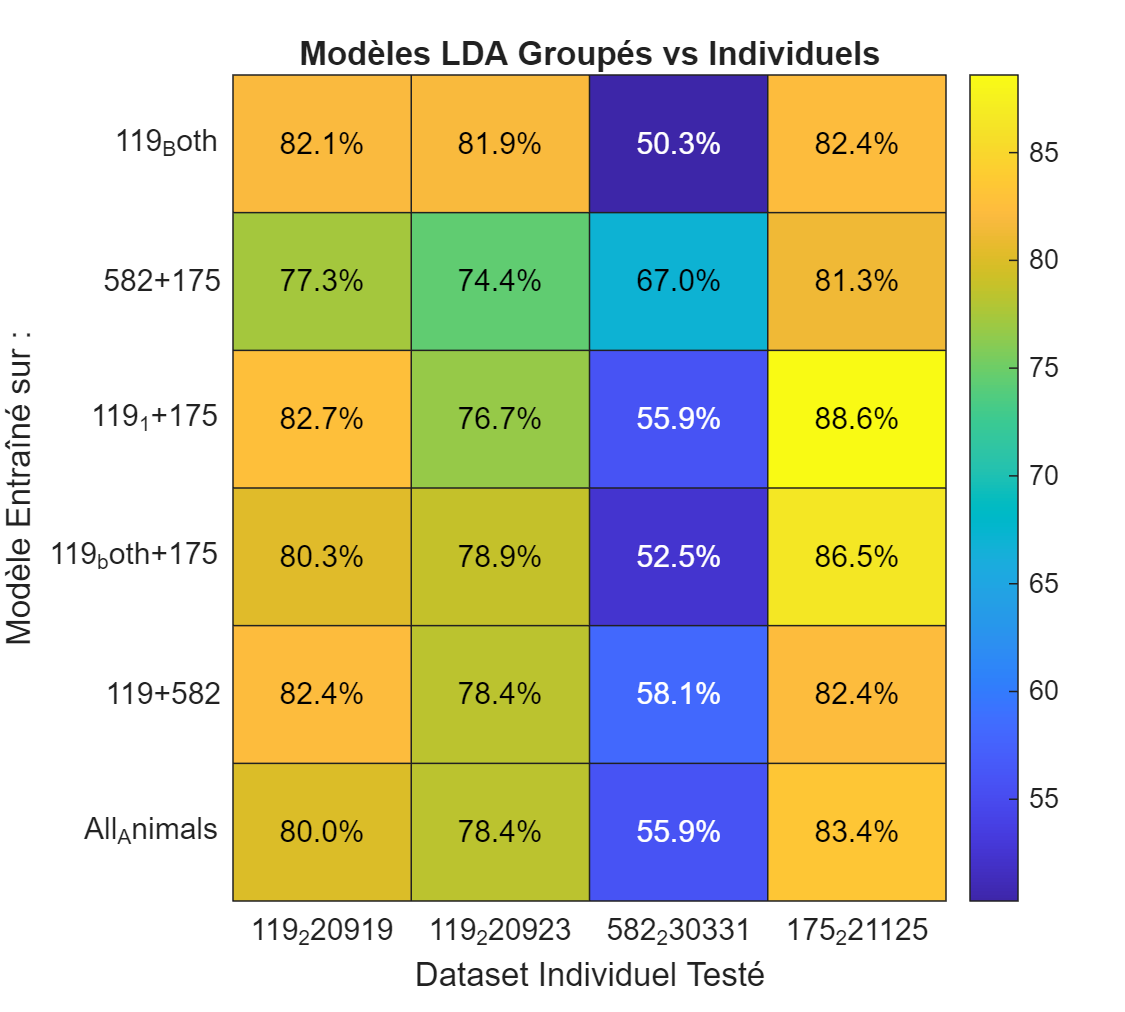


% =========================================================================
% 4. AFFICHAGE DES RÉSULTATS (HEATMAPS)
% =========================================================================
% --- Heatmap 1 : LDA ---
figure('Name', 'Combinaisons : LDA', 'Position', [100, 200, 500, 450]);
h1 = heatmap(dataset_labels, combo_labels, acc_matrix_lin);
h1.Title = 'Modèles LDA Groupés vs Individuels';
h1.XLabel = 'Dataset Individuel Testé';
h1.YLabel = 'Modèle Entraîné sur :';
h1.Colormap = parula; 
h1.CellLabelFormat = '%.1f%%'; 

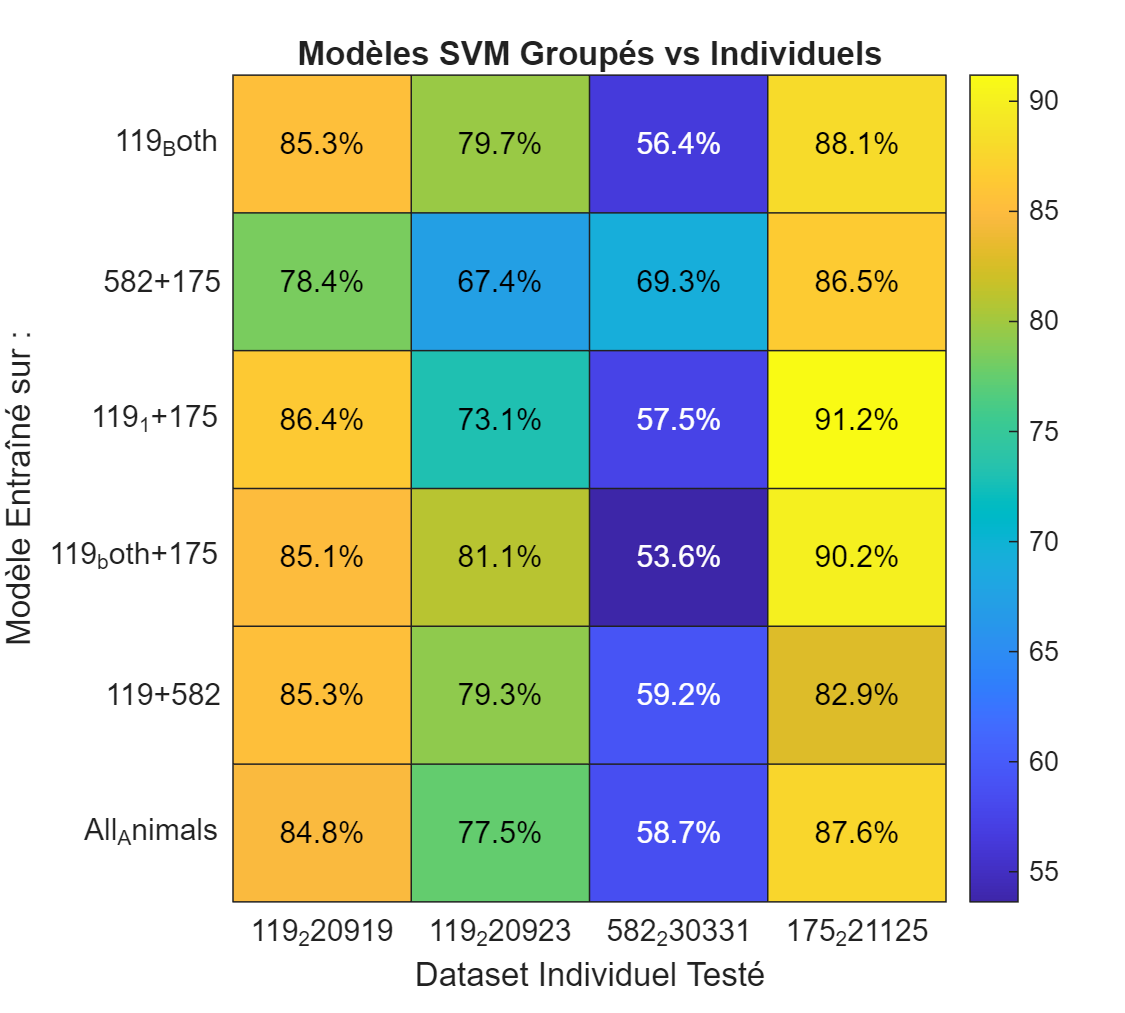


% --- Heatmap 2 : SVM ---
figure('Name', 'Combinaisons : SVM', 'Position', [600, 200, 500, 450]);
h2 = heatmap(dataset_labels, combo_labels, acc_matrix_svm);
h2.Title = 'Modèles SVM Groupés vs Individuels';
h2.XLabel = 'Dataset Individuel Testé';
h2.YLabel = 'Modèle Entraîné sur :';
h2.Colormap = parula; 
h2.CellLabelFormat = '%.1f%%'; 

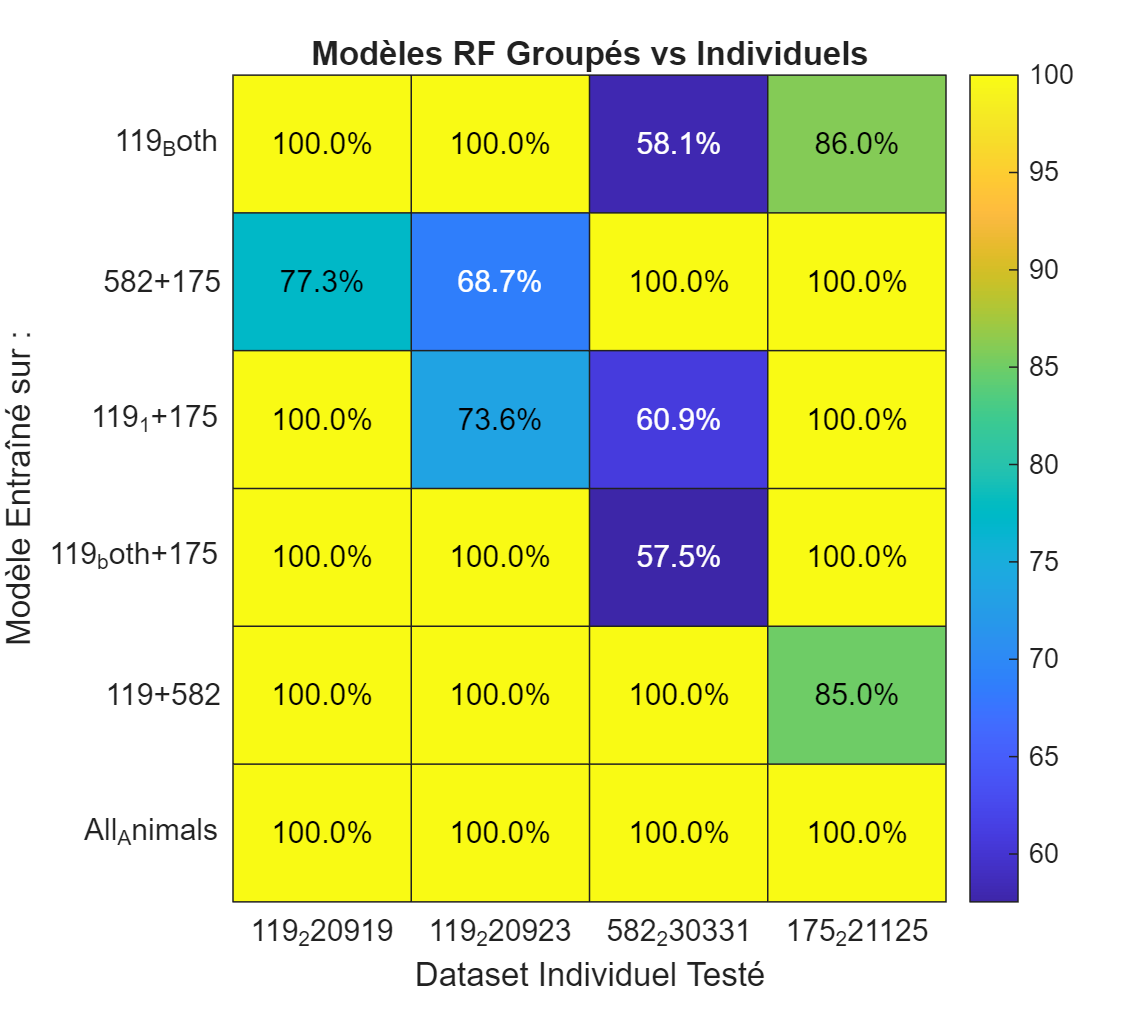


% --- Heatmap 3 : Random Forest ---
figure('Name', 'Combinaisons : Random Forest', 'Position', [1100, 200, 500, 450]);
h3 = heatmap(dataset_labels, combo_labels, acc_matrix_rf);
h3.Title = 'Modèles RF Groupés vs Individuels';
h3.XLabel = 'Dataset Individuel Testé';
h3.YLabel = 'Modèle Entraîné sur :';
h3.Colormap = parula; 
h3.CellLabelFormat = '%.1f%%'; 



% =========================================================================
% FONCTION LOCALE POUR L'ACCURACY (À garder à la fin)
% =========================================================================
function accuracy_pct_sans_noires = get_accuracy(MdlFinal, X, Ycat)
    y_pred = predict(MdlFinal, X);
    
    if iscategorical(Ycat) || ischar(Ycat)
        truth_labels = cellstr(Ycat);
    else
        truth_labels = Ycat;
    end
    pred_labels = cellstr(y_pred);
    
    % On exclut le noir/black
    idx_sans_noires = find(~strcmp(truth_labels, 'black') & ~strcmp(truth_labels, 'noir'));
    nb_total = length(idx_sans_noires);
    
    if nb_total > 0
        nb_correct = sum(strcmp(truth_labels(idx_sans_noires), pred_labels(idx_sans_noires)));
        accuracy_pct_sans_noires = (nb_correct / nb_total) * 100;
    else
        accuracy_pct_sans_noires = NaN;
    end
end
return


clear
analysis1=load ("E:\Data\Aurelie\analysis\June2026\invivo_exvivo\119_220919plane0\alignment_analysis.mat");
analysis2=load ("E:\Data\Aurelie\analysis\June2026\invivo_exvivo\119_220923plane0\alignment_analysis.mat");
analysis3=load ("E:\Data\Aurelie\analysis\June2026\invivo_exvivo\582_230331plane0\alignment_analysis.mat");
analysis4=load ("E:\Data\Aurelie\analysis\June2026\invivo_exvivo\175_221125plane0\alignment_analysis.mat");

%test modele 1 sur données 1
cell_IDs = analysis1.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(analysis1.MdlLin, analysis1.X_raw(cell_IDs, :), analysis1.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);
accuracy(1,1)=accuracy_pct_sans_noires;

%test modele 1 sur données 2
cell_IDs = analysis2.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(analysis1.MdlLin, analysis2.X_raw(cell_IDs, :), analysis2.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);
accuracy(1,2)=accuracy_pct_sans_noires;


%test modele 2 sur données 1 
cell_IDs = analysis1.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(analysis2.MdlLin, analysis1.X_raw(cell_IDs, :), analysis1.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);
accuracy(2,1)=accuracy_pct_sans_noires;

%test modele 2 sur données 1 
cell_IDs = analysis2.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(analysis2.MdlLin, analysis2.X_raw(cell_IDs, :), analysis2.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);
accuracy(2,2)=accuracy_pct_sans_noires;

%construction dataset groupé analysis 1 and 2 and 3 and 4

x_grouped = [analysis1.X_raw(analysis1.cell_IDs, :) ; analysis2.X_raw(analysis2.cell_IDs, :) ;analysis3.X_raw(analysis3.cell_IDs, :)];
% y_grouped = [analysis1.Ycat_raw(analysis1.cell_IDs, :) ; analysis2.Ycat_raw(analysis2.cell_IDs, :) ];
% analysis1.colorcell_exvivo
colorcell_grouped = [analysis1.colorcell_exvivo(analysis1.cell_IDs) ;analysis2.colorcell_exvivo(analysis2.cell_IDs);analysis3.colorcell_exvivo(analysis3.cell_IDs)]; 
% roi_red_grouped = [analysis1.roi_red_corrected(analysis1.cell_IDs) ;analysis2.colorcell_exvivo(analysis2.cell_IDs)]; 
% roi_green_grouped
% roi_blue_grouped
% roi_ca_grouped
[MdlLin_grouped, MdlSVM_grouped, MdlRF_grouped,X,Ycat, X_raw,Ycat_raw, cell_IDs] = prediction_color(colorcell_grouped,x_grouped(:,1),x_grouped(:,2),x_grouped(:,3),x_grouped(:,4));


%test modele linéaire grouped sur données 1 
cell_IDs = analysis1.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(MdlLin_grouped, analysis1.X_raw(cell_IDs, :), analysis1.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);
accuracy(3,1)=accuracy_pct_sans_noires;
%test modele grouped sur données 2
cell_IDs = analysis2.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(MdlLin_grouped, analysis2.X_raw(cell_IDs, :), analysis2.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);
accuracy(3,2)=accuracy_pct_sans_noires;
%test modele grouped sur données 3
cell_IDs = analysis3.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(MdlLin_grouped, analysis3.X_raw(cell_IDs, :), analysis3.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);
accuracy_pct_sans_noires
% accuracy(3,2)=accuracy_pct_sans_noires;

%test modele SVM grouped sur données 1
cell_IDs = analysis1.cell_IDs;
seuil_faible =0;
MdlFinal = MdlSVM_grouped;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] = test_model_all(MdlFinal, analysis1.X_raw(cell_IDs, :), analysis1.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);
%test modele grouped sur données 2
cell_IDs = analysis2.cell_IDs;
seuil_faible =0;
MdlFinal = MdlSVM_grouped;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] = test_model_all(MdlFinal, analysis2.X_raw(cell_IDs, :), analysis2.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);
%test modele grouped sur données 3
cell_IDs = analysis3.cell_IDs;
seuil_faible =0;
MdlFinal = MdlSVM_grouped;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] = test_model_all(MdlFinal, analysis3.X_raw(cell_IDs, :), analysis3.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);

%test modele grouped sur données 1
cell_IDs = analysis1.cell_IDs;
seuil_faible =0;
MdlFinal = MdlRF_grouped;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] = test_model_all(MdlFinal, analysis1.X_raw(cell_IDs, :), analysis1.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);

%test modele grouped sur données 2
cell_IDs = analysis2.cell_IDs;
seuil_faible =0;
MdlFinal = MdlRF_grouped;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] = test_model_all(MdlFinal, analysis2.X_raw(cell_IDs, :), analysis2.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);
%test modele grouped sur données 3
cell_IDs = analysis3.cell_IDs;
seuil_faible =0;
MdlFinal = MdlRF_grouped;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] = test_model_all(MdlFinal, analysis3.X_raw(cell_IDs, :), analysis3.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);



%test modele grouped sur données grouped 

seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(MdlLin_grouped, X,Ycat,1:numel(Ycat),0,seuil_faible);
accuracy(3,3)=accuracy_pct_sans_noires;

figure(visible='on');
imagesc(accuracy)
colormap ('hot')
colorbar 
clim ([70 100])

% figure(Visible='on');histogram(certitude_max,10)